## Robot's Dynamics

### Langrange Algorithm:

### Forming all Homogeneous Transformation Matrixes (A0i)

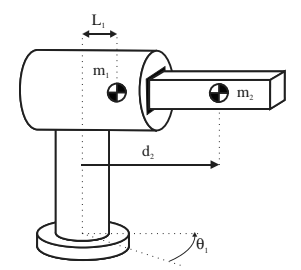      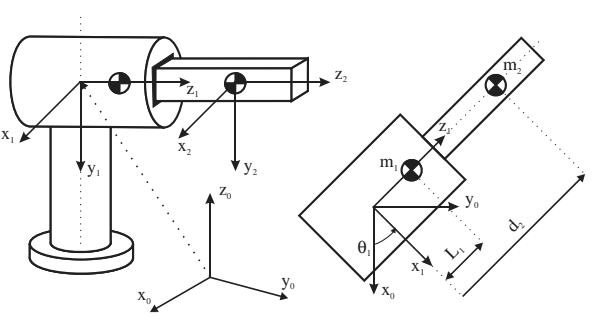

syms theta1 d2 m1 m2 l1

R1 = [cos(theta1) -sin(theta1) 0; sin(theta1) cos(theta1) 0; 0 0 1];
T1 = HTM(R1);
R2 = rotx(-90);
T2 = HTM(R2);

A01 = T1 * T2

$$A01 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & 0 & \cos\left(\theta_{1}\right) & 0\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

p = [0; 0; d2];
T = HTM(eye(3),p);

A12 = T

$$A12 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & d_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A02 = A01 * A12

$$A02 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & -d_{2}\,\sin\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & 0 & \cos\left(\theta_{1}\right) & d_{2}\,\cos\left(\theta_{1}\right)\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Solving for all Uij

Expression: Uij = dA0i/qj

where dA0i/qj is:

- [ A0(j-1) * Qj * A(j-1)i ] if j <= i

- [0] if j > i

with:

- i, j = 1, 2, ..., n

- Qi = [0 -1 0 0; 1 0 0 0; 0 0 0 0; 0 0 0 0] if i is rotational

- Qi = [0 0 0 0; 0 0 0 0; 0 0 0 1; 0 0 0 0] if i is traslational

QR = [0 -1 0 0; 1 0 0 0; 0 0 0 0; 0 0 0 0];   % Rotational Q
Qp = [0 0 0 0; 0 0 0 0; 0 0 0 1; 0 0 0 0];    % Traslational Q
Aii = HTM(eye(3));                            % HTM from i to i

U11 = Aii * QR * A01

$$U11 = \left(\begin{array}{cccc} -\sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & 0\\ \cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

% j > i case
U12 = 0;
U21 = Aii * QR * A02

$$U21 = \left(\begin{array}{cccc} -\sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & -d_{2}\,\cos\left(\theta_{1}\right)\\ \cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & -d_{2}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

U22 = A01 * Qp * A12

$$U22 = \left(\begin{array}{cccc} 0 & 0 & 0 & -\sin\left(\theta_{1}\right)\\ 0 & 0 & 0 & \cos\left(\theta_{1}\right)\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

### Solving for all Uijk

Expression: Uijk = d( dA0i/qj )/qk

where d( dA0i/qj )/qk is:

- [ A0(j-1) * Qj * A(j-1)(k-1) * Qk * A(k-1)i ] if i >= k >= j

- [ A0(k-1) * Qk * A(k-1)(j-1) * Qj * A(j-1)i ] if i >= j >= k

- [0] if k > i or k > j

with:

- i, j, k = 1, 2, ..., n

- Qi same as Uij

U111 = Aii * QR * Aii * QR * A01

$$U111 = \left(\begin{array}{cccc} -\cos\left(\theta_{1}\right) & 0 & \sin\left(\theta_{1}\right) & 0\\ -\sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

U112 = 0;
U121 = 0;
U122 = 0;
U211 = Aii * QR * Aii * QR * A02

$$U211 = \left(\begin{array}{cccc} -\cos\left(\theta_{1}\right) & 0 & \sin\left(\theta_{1}\right) & d_{2}\,\sin\left(\theta_{1}\right)\\ -\sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & -d_{2}\,\cos\left(\theta_{1}\right)\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

U212 = Aii * QR * A01 * Qp * A12

$$U212 = \left(\begin{array}{cccc} 0 & 0 & 0 & -\cos\left(\theta_{1}\right)\\ 0 & 0 & 0 & -\sin\left(\theta_{1}\right)\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

U221 = Aii * QR * A01 * Qp * A12

$$U221 = \left(\begin{array}{cccc} 0 & 0 & 0 & -\cos\left(\theta_{1}\right)\\ 0 & 0 & 0 & -\sin\left(\theta_{1}\right)\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

U222 = A01 * Qp * Aii * Qp * A12;        % same as [0]

### Solving for PseudoInertias Ji (4×4)

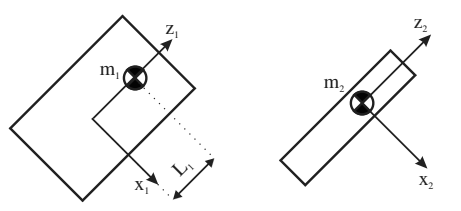

where:

- Ji(1,1:end) = [ int(xi^2, mi) int(xi * yi, mi) int(xi * zi, mi) int(xi, mi) ]

- Ji(2,1:end) = [ int(yi * xi, mi) int(yi^2, mi) int(yi * zi, mi) int(yi, mi) ]

- Ji(3,1:end) = [ int(zi * xi, mi) int(zi * yi, mi) int(zi^2, mi) int(zi, mi) ]

- Ji(4,1:end) = [ int(xi, mi) int(yi, mi) int(zi, mi) int(1, mi) ]

with:

- i = 1, 2, ..., n

x1 = 0;
y1 = 0;
z1 = l1;
J1 = [int(x1^2, m1) int(x1 * y1, m1) int(x1 * z1, m1) int(x1, m1); ...
      int(y1 * x1, m1) int(y1^2, m1) int(y1 * z1, m1) int(y1, m1); ...
      int(z1 * x1, m1) int(z1 * y1, m1) int(z1^2, m1) int(z1, m1); ...
      int(x1, m1) int(y1, m1) int(z1, m1) int(1, m1)]

$$J1 = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & {l_{1}}^{2}\,m_{1} & l_{1}\,m_{1}\\ 0 & 0 & l_{1}\,m_{1} & m_{1} \end{array}\right)$$

x2 = 0;
y2 = 0;
z2 = 0;
J2 = [int(x2^2, m2) int(x2 * y2, m2) int(x2 * z2, m2) int(x2, m2); ...
      int(y2 * x2, m2) int(y2^2, m2) int(y2 * z2, m2) int(y2, m2); ...
      int(z2 * x2, m2) int(z2 * y2, m2) int(z2^2, m2) int(z2, m2); ...
      int(x2, m2) int(y2, m2) int(z2, m2) int(1, m2)]

$$J2 = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & m_{2} \end{array}\right)$$

### Solving for Inertia Matrixes D

Expression: D = dij

where:

- dij = Sum (from k=max(i, j) to n) of [ Trace(Ukj * Jk * Ukj^T) ]

with:

- i, j = 1, 2, ..., n

d11 = simplify(trace(U11 * J1 * U11.' + U21 * J2 * U21.'))

$$d11 = m_{2}\,{d_{2}}^{2}+m_{1}\,{l_{1}}^{2}$$

d12 = trace(U22 * J2 * U21.')

$$d12 = 0$$

d21 = trace(U21 * J2 * U22.')

$$d21 = 0$$

d22 = simplify(trace(U22 * J2 * U22.'))

$$d22 = m_{2}$$

D = [d11 d12; d21 d22]

$$D = \left(\begin{array}{cc} m_{2}\,{d_{2}}^{2}+m_{1}\,{l_{1}}^{2} & 0\\ 0 & m_{2} \end{array}\right)$$

### **Solving for hikm**

where:

- hikm = Sum (from j=max(i,k,m) to n) of [ Ujkm * Jj * Uji^T ]

with:

- i, k, m = 1, 2, ..., n

h111 = simplify(trace(U111 * J1 * U11.' + U211 * J2 * U21.'))

$$h111 = 0$$

h112 = simplify(trace(U212 * J2 * U21.'))

$$h112 = d_{2}\,m_{2}$$

h121 = simplify(trace(U221 * J2 * U21.'))

$$h121 = d_{2}\,m_{2}$$

h122 = simplify(trace(U222 * J2 * U21.'))

$$h122 = 0$$

h211 = simplify(trace(U211 * J2 * U22.'))

$$h211 = -d_{2}\,m_{2}$$

h212 = simplify(trace(U212 * J2 * U22.'))

$$h212 = 0$$

h221 = simplify(trace(U221 * J2 * U22.'))

$$h221 = 0$$

h222 = simplify(trace(U222 * J2 * U22.'))

$$h222 = 0$$

### Solving for H

Expression: H = [ hi ]^T

where:

- hi = Sum (from k=1 to n) of [ Sum (from m=1 to n) of [ hikm * qdot_k * qdot_m ] ]

with:

- i = 1, 2, ..., n

syms theta1_dot d2_dot

h1 = h111 * theta1_dot * theta1_dot + h112 * theta1_dot * d2_dot + ...
     h121 * d2_dot * theta1_dot + h122 * d2_dot * d2_dot

$$h1 = 2\,d_{2}\,d_{\dot{2}}\,m_{2}\,\theta_{\dot{1}}$$

h2 = h211 * theta1_dot * theta1_dot + h212 * theta1_dot * d2_dot + ...
     h221 * d2_dot * theta1_dot + h222 * d2_dot * d2_dot

$$h2 = -d_{2}\,m_{2}\,{\theta_{\dot{1}}}^{2}$$

H = [h1 h2].'

$$H = \left(\begin{array}{c} 2\,d_{2}\,d_{\dot{2}}\,m_{2}\,\theta_{\dot{1}}\\ -d_{2}\,m_{2}\,{\theta_{\dot{1}}}^{2} \end{array}\right)$$

### Solving for C

Expression: C = [ ci ]^T

where:

- ci = Sum (from j=1 to n) of [ -mj * g * Uji * rjj ]

with:

- i = 1, 2, ..., n

- g: Gravity vector expressed at S0's base and is expressed by (gx0 gy0 gx0 0)

- rij: Homogeneous coordinates vector of element j's center of gravity, expressed in frame i.

syms g

G = [0 0 -g 0];
r11 = [0 0 l1 1].';
r22 = [0 0 0 1].';

c1 = -m1 * G * U11 * r11 + -m2 * G * U21 * r22

$$c1 = 0$$

c2 = -m1 * G * U12 * r11 + -m2 * G * U22 * r22

$$c2 = 0$$

C = [c1 c2].'

$$C = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

### Forming system's dynamic equation (tau)

Expression: tau = D * qddot + H + C

where:

- tau is the vector of effective forces and torques applied to every coordinate qi

syms theta1_ddot d2_ddot

q_ddot = [theta1_ddot d2_ddot].';

tau = D * q_ddot + H + C;

% Effective torque applied to articulation 1
T1 = tau(1)

$$T1 = \theta_{\ddot{1}}\,\left(m_{2}\,{d_{2}}^{2}+m_{1}\,{l_{1}}^{2}\right)+2\,d_{2}\,d_{\dot{2}}\,m_{2}\,\theta_{\dot{1}}$$

% Effective force applied to articulation 2
F2 = tau(2)

$$F2 = d_{\ddot{2}}\,m_{2}-d_{2}\,m_{2}\,{\theta_{\dot{1}}}^{2}$$

% No force nor torque required to counteract gravity

### Different case scenario

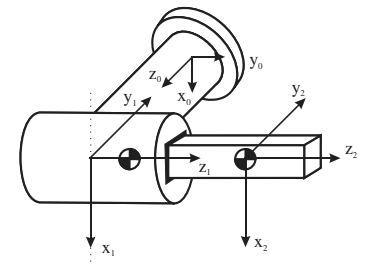

% Recalculating C vector
G = [g 0 0 0];
r11 = [0 0 l1 1].';
r22 = [0 0 0 0].';

c1 = -m1 * G * U11 * r11 + -m2 * G * U21 * r22

$$c1 = g\,l_{1}\,m_{1}\,\cos\left(\theta_{1}\right)$$

c2 = -m1 * G * U12 * r11 + -m2 * G * U22 * r22

$$c2 = 0$$

C = [c1 c2].'

$$C = \left(\begin{array}{c} g\,l_{1}\,m_{1}\,\cos\left(\theta_{1}\right)\\ 0 \end{array}\right)$$

% Recalculating tau
tau = D * q_ddot + H + C;

% Effective torque applied to articulation 1
T1 = tau(1)

$$T1 = \theta_{\ddot{1}}\,\left(m_{2}\,{d_{2}}^{2}+m_{1}\,{l_{1}}^{2}\right)+2\,d_{2}\,d_{\dot{2}}\,m_{2}\,\theta_{\dot{1}}+g\,l_{1}\,m_{1}\,\cos\left(\theta_{1}\right)$$

% Effective force applied to articulation 2
F2 = tau(2)

$$F2 = d_{\ddot{2}}\,m_{2}-d_{2}\,m_{2}\,{\theta_{\dot{1}}}^{2}$$